clc;
clear;

% fv = [Flf, Fcf, Nf, Frr_f, Flr, Fcr, Nr, Frr_r, f_adx, f_ady, b.tau_t, delta,...
%                         vlf, vcf, omega_f, b.sf, beta_f, vlr, vcr, omega_r, b.sr, beta_r]
% bekk_h = [-int_sig_sin_f, int_tau_cos_f, thf_f, thr_f, thm_f, hf_f,
%                 -int_sig_sin_r, int_tau_cos_r, thf_r, thr_r, thm_r, hf_r]
% sig_tau = [sig_f, tau_xf, sig_r, tau_xr]


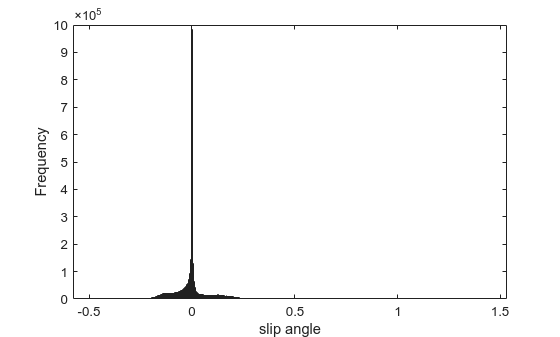

load('../../datasets/sandyloam_100hz_no_elev_experiment_1579.mat','exp_fv','exp_bekk_h')


beta = []; sr = [];v=[];hf=[];
for i=1:size(exp_fv,2)
    exp_1 = exp_fv{i};
    exp_2 = exp_bekk_h{i};
    beta = [beta;exp_1(:,17);exp_1(:,22)];
    sr = [sr;exp_1(:,16);exp_1(:,21)];
    v = [v;exp_1(:,14);exp_1(:,19)];
    hf = [hf;exp_2(:,6);exp_2(:,12)];
end
histogram(beta);
xlabel('slip angle');
ylabel('Frequency');

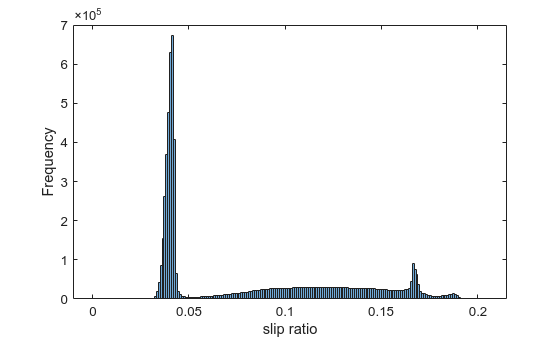

% title('Histogram of all sinkage values');

histogram(sr);
xlabel('slip ratio');
ylabel('Frequency');

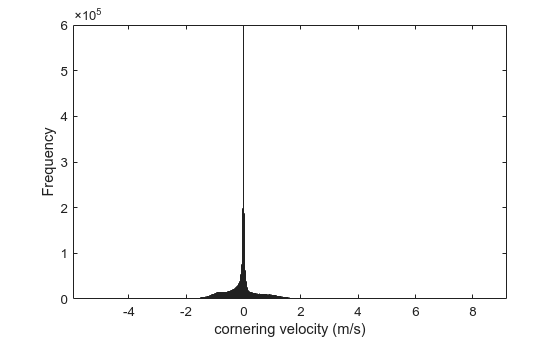

% title('Histogram of all sinkage values');

histogram(v);
xlabel('cornering velocity (m/s)');
ylabel('Frequency');

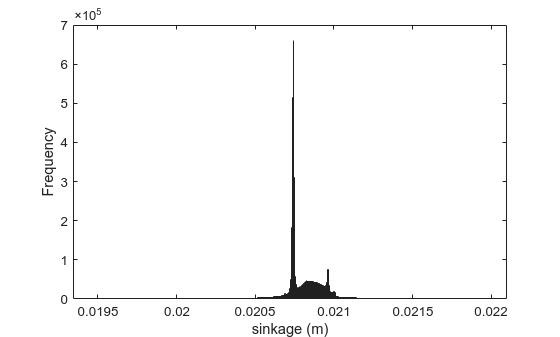

% title('Histogram of all sinkage values');

histogram(hf);
xlabel('sinkage (m)');
ylabel('Frequency');

% title('Histogram of all sinkage values');


addpath("clay_Elev_dataset_100hz")

% Get list of all matching files
files = dir('clay_Elev_dataset_100hz/data_*.mat');

all_vals = []; % container for all b.fv values
time_step = [];
for k = 1:length(files)
    data = load(files(k).name,"fv","t_hc");
    % Access nested structure: b.fv
    % all_vals = [all_vals; data.fv(:,21.')];
    % time_step = [time_step; data.t_hc];
    if size(data.fv(:,21),1) ==2001
        all_vals = [all_vals data.fv(:,22)];
    end
end
% Bin edges for histogram
edges = linspace(0, 1, 200);

% Bin counts
[N,~,bin] = histcounts(all_vals, edges);
% Plot colored histogram bars
step = [0, 400, 800, 1200, 1600]

step =            0         400         800        1200        1600


figure;
for i=5:-1:1
    all_val = all_vals(step(i)+(1:400),:);
    histogram(all_val);
    hold on;
end

Index in position 1 exceeds array bounds.

legend('1','2','3','4','5')

% colormap(jet);
% colorbar;
% xlabel('X values');
% ylabel('Frequency');
% title('Histogram colored by mean Z');

 % Plot histogram with automatic binning
bar3(all_vals,time_step);
xlabel('b.fv values');
ylabel('Frequency');
title('Histogram of all slip ratio values');

for k = 1:length(files)
    data = load(files(k).name,"bekk_h");
    % Access nested structure: b.fv
    all_vals = [all_vals; data.bekk_h(:,12)];
end

% Plot histogram with automatic binning
histogram(all_vals);
xlabel('b.fv values');
ylabel('Frequency');
title('Histogram of all sinkage values');


addpath("sandyloam_noElev_dataset_100hz")
% Get list of all matching files
files = dir('sandyloam_noElev_dataset_100hz/data_*.mat');

all_vals = []; % container for all b.fv values

for k = 1:length(files)
    data = load(files(k).name,"fv");
    % Access nested structure: b.fv
    all_vals = [all_vals; data.fv(:,20)];
end

% Plot histogram with automatic binning
histogram(all_vals);
xlabel('b.fv values');
ylabel('Frequency');
title('Histogram of all slip ratio values');

for k = 1:length(files)
    data = load(files(k).name,"bekk_h");
    % Access nested structure: b.fv
    all_vals = [all_vals; data.bekk_h(:,12)];
end

% Plot histogram with automatic binning
histogram(all_vals);
xlabel('b.fv values');
ylabel('Frequency');
title('Histogram of all sinkage values');

% Example data
x = randn(1000,1);    % main variable
z = rand(1000,1)*10;  % secondary variable for color

% Bin edges for histogram
edges = linspace(min(x), max(x), 20);

% Bin counts
[N,~,bin] = histcounts(x, edges);

% Compute mean z per bin
meanZ = accumarray(bin(bin>0), z(bin>0), [], @mean);

% Plot colored histogram bars
figure;
hold on;
for i = 1:length(N)
    bar(edges(i), N(i), 'FaceColor', barColor, 'EdgeColor', 'none');
end
hold off;

colormap(jet);
colorbar;
xlabel('X values');
ylabel('Frequency');
title('Histogram colored by mean Z');

% Example data
x = randn(1000,1);
z = rand(1000,1)*10;

% 2D histogram where color represents counts or z intensity
histogram2(x, z, 30, 30, 'DisplayStyle', 'tile');
colorbar;
xlabel('X values');
ylabel('Z values');
title('2D Histogram (color = count)');

x = randn(1000,1);
z = rand(1000,1)*10;

[counts, edges] = histcounts(x, 30);
binCenters = edges(1:end-1) + diff(edges)/2;

scatter(binCenters, counts, 60, meanZ, 'filled'); % color by meanZ
colormap(jet);
colorbar;
xlabel('X values');
ylabel('Frequency');
title('Histogram with color-coded bins');
